clear
% Define the folder path
folderPath = 'HDR/JPG'; % Adjust the path as necessary
%folderPath = 'images'; % Adjust the path as necessary

% Create an imageDatastore for all JPG files in the folder
imds = imageDatastore(folderPath, 'FileExtensions', '.JPG');
%imds = imageDatastore(folderPath, 'FileExtensions', '.jfif');

% Display the number of images found
numImages = numel(imds.Files);
disp(['Number of JPG images found: ', num2str(numImages)]);

% Read the i-th image from the datastore
img = readimage(imds, 1);

% Display the image
imshow(img);
title('Image from the Datastore');
img = readimage(imds, numImages);
imshow(img);
title('Image from the Datastore');





%Ranom Sampling of pixels
[H, W, C] = size(img); % read image Height, Width, Channel. Assumed same for all images duuh

numSamples = 200;
rng(0);
% meshgrid avoids sample clustering. grid bias + random.
[Xs, Ys] = meshgrid(round(linspace(1,W,round(sqrt(numSamples)))), round(linspace(1,H,sqrt(numSamples))));
coord = [Xs(:),Ys(:)];
if size(coord, 1) < numSamples
    extra = numSamples - size(coord,1);
    randCoord = [randi(W, extra, 1), randi(H, extra, 1)];
    coord = [coord; randCoord];
else
    coord = coord(1:numSamples,:);
end
% I orginal artikeln så nämns det att de kastade även ut väldigt saturerade
% värden dvs 255


exposureTimes = zeros(numImages,1);
for j = 1:numImages
    info = imfinfo(imds.Files{j});
    exposureTimes(j) = info.DigitalCamera.ExposureTime;
end

B = log(exposureTimes);

% Hat weight 
Zmin = 0;
Zmax = 255;
Zmid = Zmax/2;
wvec = zeros(256, 1);
for z = Zmin:Zmax
    if z <= Zmid
        wvec(z+1) = z - Zmin;
    else
        wvec(z+1) = Zmax -z;
    end
end


% Plot wvec against its indices
plot(wvec, 'LineWidth', 2);
xlim([1 length(wvec)]);
title('Plot of wvec');
xlabel('Index');
ylabel('Value');
grid on
axis square;


% Sample pixel values for each channel separately
Z_red = zeros(numSamples, numImages);
Z_green = zeros(numSamples, numImages);
Z_blue = zeros(numSamples, numImages);

Z_clip_min = 1;
Z_clip_max = 254;

for j = 1:numImages
    Ij = im2double(readimage(imds, j));
    Ij = rgb2lin(Ij);
    for i = 1:numSamples
            
            Ztemp = round(Ij(coord(i,2), coord(i,1),:) * 255);
            if all(Ztemp >= Z_clip_min & Ztemp <= Z_clip_max)
                Z_red(i,j) = Ztemp(1);
                Z_green(i,j) = Ztemp(2);
                Z_blue(i,j) = Ztemp(3);
            end
    end
end

lambda = 100;
[g_red, lE_red] = gsolve(Z_red, B, lambda, wvec);
[g_green, lE_green] = gsolve(Z_green, B, lambda, wvec);
[g_blue, lE_blue] = gsolve(Z_blue, B, lambda, wvec);

% Combine into a singular g
g = {g_red, g_green, g_blue};

%Load all images (now with colour)
for j = 1:numImages

    Ij = im2double(imread(imds.Files{j}));
    Ij = rgb2lin(Ij); %sRGB to linear RGB behövs för korrekt algo
    %No CIELAB should be used because the algoritim needs accurate
    %radiometric values

    if j == 1 
        [H,W,C] = size(Ij);
        images = zeros(H,W,C,numImages);

    end 
    images(:,:,:,j) = Ij;
end 


%reconstruct image in .hdr (Radiance) 
lnE = zeros(H,W,C);

for ch = 1:C
    for y = 1:H
        for x = 1:W
            num = 0;
            den = 0;
            for j = 1:numImages
                % Pixel value in [0,255] for channel ch
                z = round(images(y,x,ch,j) * 255);

                % Clamp
                z = max(0, min(255, z));

                wij = wvec(z+1);
                num = num + wij * (g{ch}(z+1) - B(j));  % g per channel
                den = den + wij;
            end

            if den > 0
                lnE(y,x,ch) = num / den;
            else
                lnE(y,x,ch) = 0;
            end
        end
    end
end


% Read camera curve, named gfun
load("HDR\gfun.mat")

% Convert gfun to 1x3 cell array
gfunE = cell(1, C);
for ch = 1:C
    gfunE{ch} = gfun(:, ch);
end
%reconstruct image in .hdr with camera response (Radiance) 
lnE_cam = zeros(H,W,C);

for ch = 1:C
    for y = 1:H
        for x = 1:W
            num = 0;
            den = 0;
            for j = 1:numImages
                % Pixel value in [0,255] for channel ch
                z = round(images(y,x,ch,j) * 255);

                % Clamp
                z = max(0, min(255, z));

                wij = wvec(z+1);
                num = num + wij * (gfunE{ch}(z+1) - B(j));  % g per channel
                den = den + wij;
            end

            if den > 0
                lnE_cam(y,x,ch) = num / den;
            else
                lnE_cam(y,x,ch) = 0;
            end
        end
    end
end


figure; hold on;

cols = {'r','g','b'};
labels = {'Recovered R','Recovered G','Recovered B', ...
          'Camera R','Camera G','Camera B'};

for ch = 1:3
    % recovered
    plot(g{ch}, 0:255, cols{ch}, 'LineWidth', 2);
    % camera-provided (dashed)
    plot(gfunE{ch}, 0:255, [cols{ch} '--'], 'LineWidth', 2);
end

ylabel('Pixel value z');
xlabel('log exposure g(z)');
title('Camera Response Functions (Recovered vs Camera gfun)');
legend(labels, 'Location','best');
grid on;
axis tight;



% vad ska vi göra med kameran btw?
HDR = exp(lnE);
%HDR3 = repmat(HDR, [1, 1, 3])
hdrwrite(single(HDR), 'result.hdr'); 
%Result blir nästan helt vit när man kollar i photoshop
% hade dock inte hdr-läge på men men. 

% Nu använder den:
% edge-preserving decompositions for multiscale tone and detail manipulation
% tonemap men vi ska göra egen eller något sånt. 
LDR_final = tonemapfarbman(HDR, 'Exposure', 1.2);
%LDR_final = tonemapfarbman(HDR);
imshow(LDR_final)
title('tonemapfarbman')

HDR_cam = exp(lnE_cam);
LDR_final_cam = tonemapfarbman(HDR_cam, 'Exposure', 1.2);
imshow(LDR_final_cam)
title('tonemapfarbman with camera response gfun')


% Apply the global tone mapping filter     Reinhard
Vin = HDR;
delta = 0.001;
[sizeX, sizeY, sizeZ] = size(Vin); 

luminanceMapHDR = 0.2126 * Vin(:,:,1) + 0.7152 * Vin(:,:,2) + 0.0722 * Vin(:,:,3);

numPixels = sizeX * sizeY
sumLog = 0;
for x=1:sizeX
    for y=1:sizeY
        sumLog = sumLog + log(delta + luminanceMapHDR(x,y));
    end
end

logAverageSmallLuminance = exp((1/numPixels) * sumLog)

a = 0.9; % key value

scaledLuminanceMap = a * luminanceMapHDR/ logAverageSmallLuminance;

newLuminanceMap = scaledLuminanceMap ./ (scaledLuminanceMap + 1);

% need to convert new luminance to an image with colour
% Gradient Domain High Dynamic Range Compression
% https://www.cs.huji.ac.il/~danix/hdr/hdrc.pdf
saturation = 0.6;
Vout = (Vin./luminanceMapHDR).^saturation .* newLuminanceMap;

% Display the original and tone-mapped images
figure;
imshow(Vout);
title('Global Tone Mapped Image (Reinhard) with gsolve response curve');



Vin = HDR_cam;
delta = 0.001;
[sizeX, sizeY, sizeZ] = size(Vin); 

luminanceMapHDR = 0.2126 * Vin(:,:,1) + 0.7152 * Vin(:,:,2) + 0.0722 * Vin(:,:,3);

numPixels = sizeX * sizeY
sumLog = 0;
for x=1:sizeX
    for y=1:sizeY
        sumLog = sumLog + log(delta + luminanceMapHDR(x,y));
    end
end

logAverageSmallLuminance = exp((1/numPixels) * sumLog)

scaledLuminanceMap = a * luminanceMapHDR/ logAverageSmallLuminance;

newLuminanceMap = scaledLuminanceMap ./ (scaledLuminanceMap + 1);

% need to convert new luminance to an image with colour
% Gradient Domain High Dynamic Range Compression
% https://www.cs.huji.ac.il/~danix/hdr/hdrc.pdf
Vout = (Vin./luminanceMapHDR).^saturation .* newLuminanceMap;

% Display the original and tone-mapped images
figure;
imshow(Vout);
title('Global Tone Mapped Image (Reinhard) with camera response curve');

mesh(newLuminanceMap)

figure;
plot(log(Vin(:,:,1)), Vout(:,:,1), 'r-', 'LineWidth', 2);
hold on
title('Tone Mapping: V_{out} over log(V_{in})');
xlabel('V_{in}');
ylabel('V_{out}');
grid on;
hold off

% Extended Reinhard
% https://64.github.io/tonemapping/#extended-reinhard
Vin2 = HDR;
delta = 0.001;
[sizeX, sizeY, sizeZ] = size(Vin2); 

luminanceMapHDR = 0.2126 * Vin2(:,:,1) + 0.7152 * Vin2(:,:,2) + 0.0722 * Vin2(:,:,3);

numPixels = sizeX * sizeY

numPixels = 6291456

sumLog = 0;
for x=1:sizeX
    for y=1:sizeY
        sumLog = sumLog + log(delta + luminanceMapHDR(x,y));
    end
end

logAverageSmallLuminance = exp((1/numPixels) * sumLog)

logAverageSmallLuminance = 3.0066

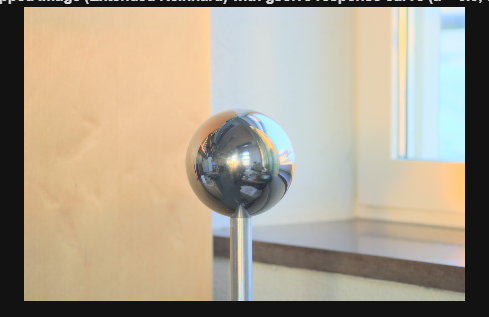


a = 0.9;%0.90; % key value

scaledLuminanceMap = a * luminanceMapHDR/ logAverageSmallLuminance;

max_white = max(max(scaledLuminanceMap));
numerator = scaledLuminanceMap .* (1.0 + (scaledLuminanceMap ./ (max_white .* max_white)));
newLuminanceMap = numerator ./ (1.0 + scaledLuminanceMap);

% need to convert new luminance to an image with colour
% Gradient Domain High Dynamic Range Compression
% https://www.cs.huji.ac.il/~danix/hdr/hdrc.pdf
saturation = 0.6;
Vout2 = (Vin2./luminanceMapHDR).^saturation .* newLuminanceMap;

% Display the original and tone-mapped images
figure;
imshow(Vout2);
title('Global Tone Mapped Image (Extended Reinhard) with gsolve response curve (a = 0.9, saturation = 0.6)');





Vin2 = HDR_cam;
delta = 0.001;
[sizeX, sizeY, sizeZ] = size(Vin2); 

luminanceMapHDR = 0.2126 * Vin2(:,:,1) + 0.7152 * Vin2(:,:,2) + 0.0722 * Vin2(:,:,3);

numPixels = sizeX * sizeY

numPixels = 6291456

sumLog = 0;
for x=1:sizeX
    for y=1:sizeY
        sumLog = sumLog + log(delta + luminanceMapHDR(x,y));
    end
end
% use Exponential of the average instead of Average of logarithms:
logAverageSmallLuminance = exp((1/numPixels) * sumLog)

logAverageSmallLuminance = 2.6672

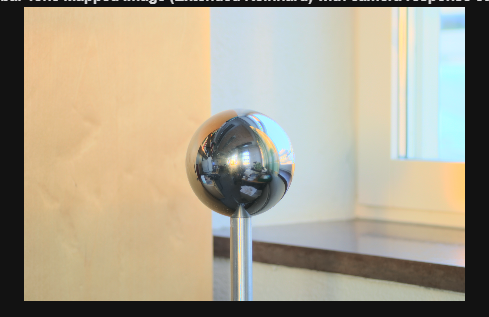


scaledLuminanceMap = a * luminanceMapHDR/ logAverageSmallLuminance;

max_white = max(max(scaledLuminanceMap));
numerator = scaledLuminanceMap .* (1.0 + (scaledLuminanceMap ./ (max_white .* max_white)));
newLuminanceMap = numerator ./ (1.0 + scaledLuminanceMap);

% need to convert new luminance to an image with colour
% Gradient Domain High Dynamic Range Compression
% https://www.cs.huji.ac.il/~danix/hdr/hdrc.pdf
Vout2 = (Vin2./luminanceMapHDR).^saturation .* newLuminanceMap;

% Display the original and tone-mapped images
figure;
imshow(Vout2);
title('Global Tone Mapped Image (Extended Reinhard) with camera response curve');

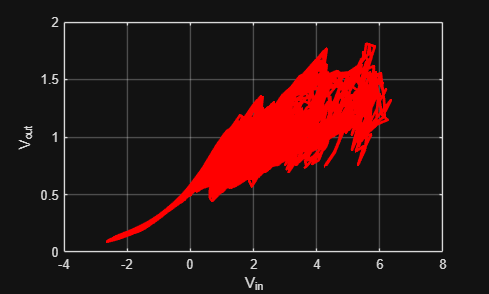

figure;
plot(log(Vin2(:,:,1)), Vout2(:,:,1), 'r-', 'LineWidth', 2);
hold on
%plot(log(Vin(:,:,1)), Vout(:,:,1), 'b--');
%title('Reinhard vs Extended Reinhard');
xlabel('V_{in}');
ylabel('V_{out}');
grid on;
hold off

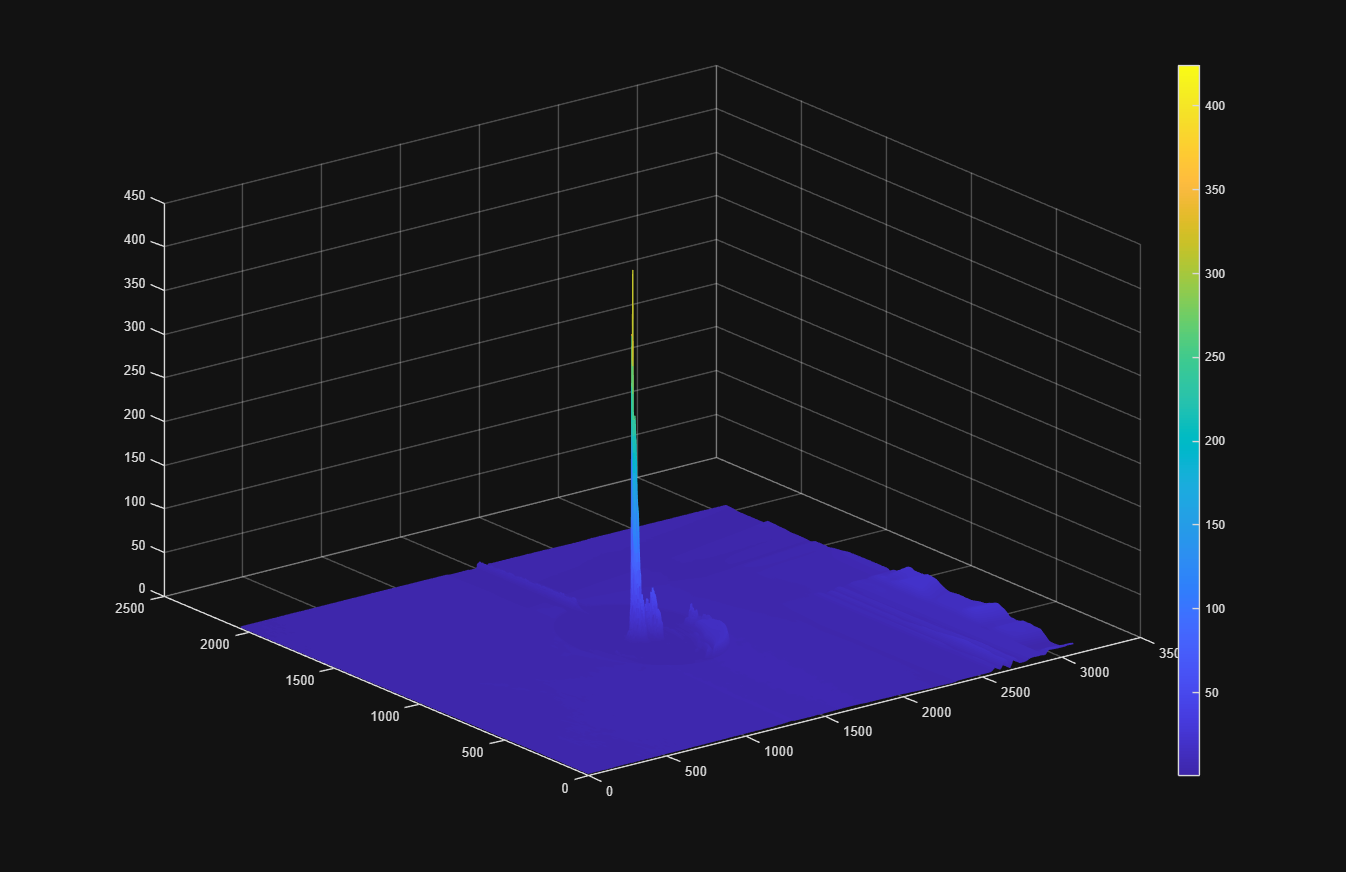

mesh(luminanceMapHDR)
colorbar

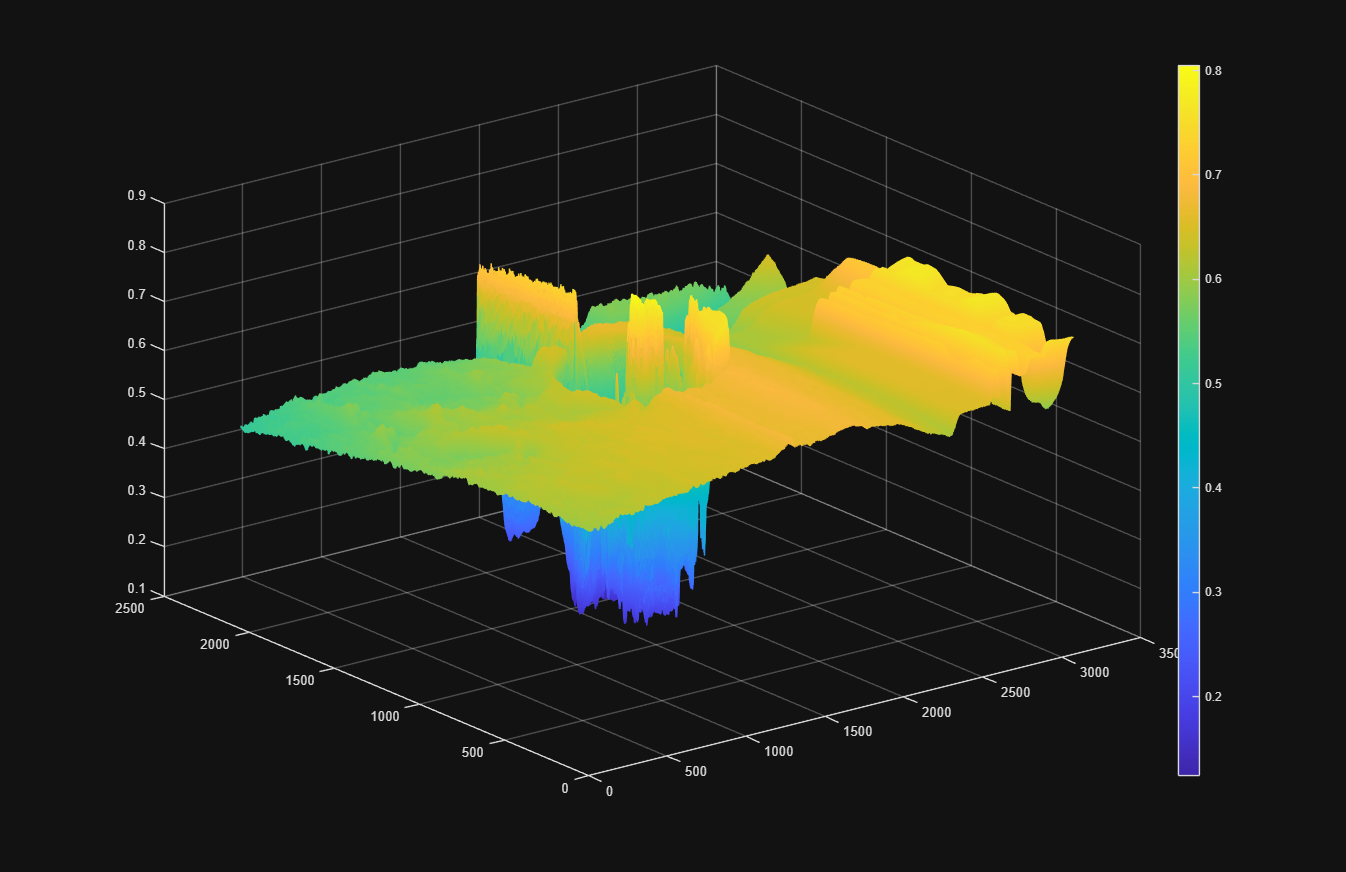

mesh(newLuminanceMap)
colorbar

highValue = max(max(max(abs(Vout-Vout2))))

highValue = 0.0084

scaleFac = 10 / highValue

scaleFac = 1.1964e+03

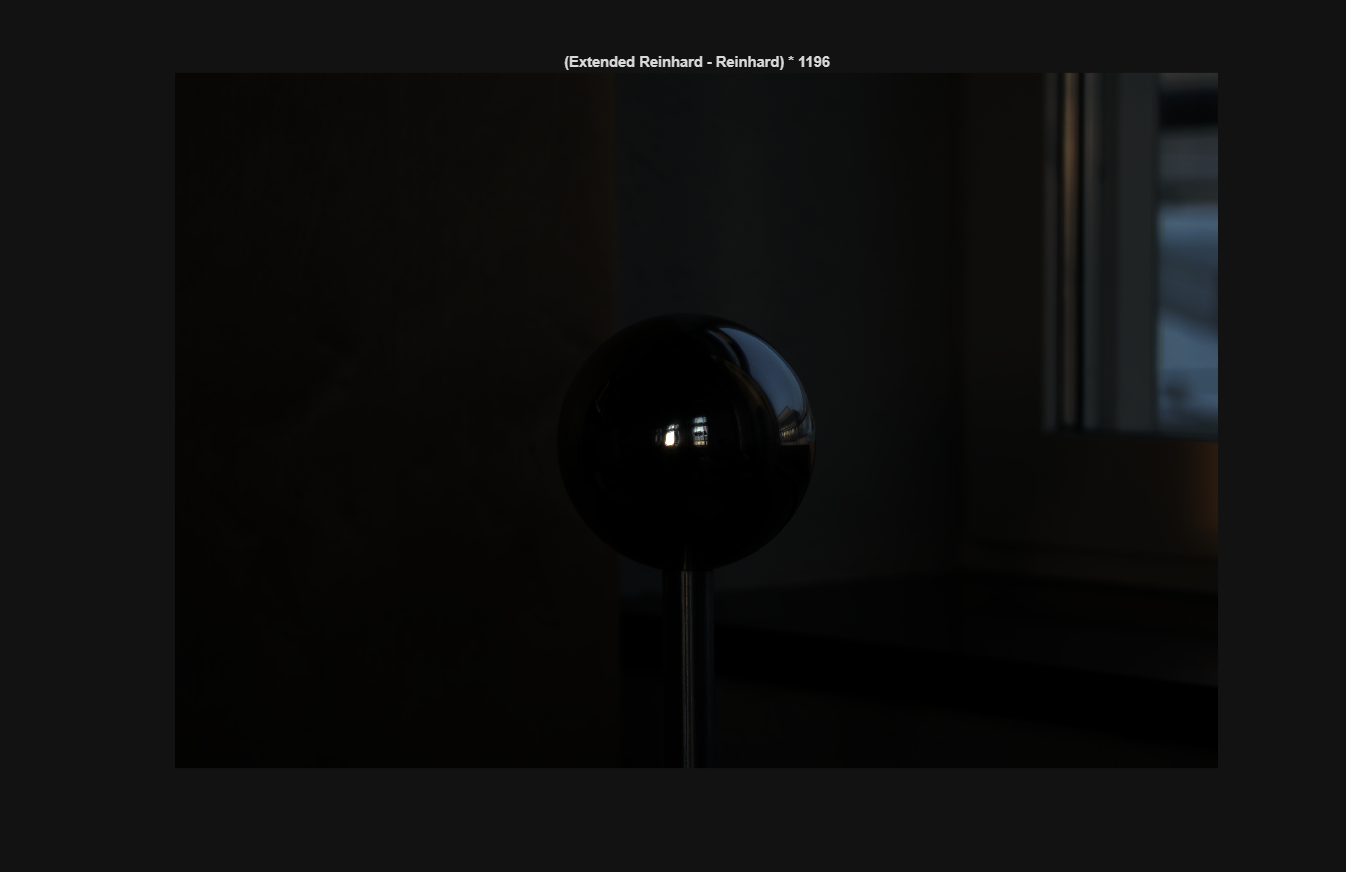

imshow(abs(Vout-Vout2) * scaleFac)
title('(Extended Reinhard - Reinhard) * 1196');

% Extended Reinhard (Luminance Tone Map)
Vin3 = HDR;
size(Vin3)

ans =         2048        3072           3



luminanceMapHDR = 0.2126 * Vin3(:,:,1) + 0.7152 * Vin3(:,:,2) + 0.0722 * Vin3(:,:,3);

numPixels = sizeX * sizeY

numPixels = 6291456

sumLog = 0;
for x=1:sizeX
    for y=1:sizeY
        sumLog = sumLog + log(delta + luminanceMapHDR(x,y));
    end
end
% use Exponential of the average instead of Average of logarithms:
logAverageSmallLuminance = exp((1/numPixels) * sumLog)

logAverageSmallLuminance = 3.0066

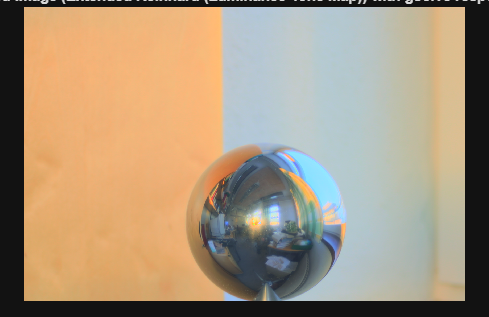


a = 3.3;

scaledLuminanceMap = a * luminanceMapHDR/ logAverageSmallLuminance;

Vout3 = Vin3 ./ (1+scaledLuminanceMap);
figure;
imshow(Vout3);
title('Global Tone Mapped Image (Extended Reinhard (Luminance Tone Map)) with gsolve response curve (a = 3.3)');

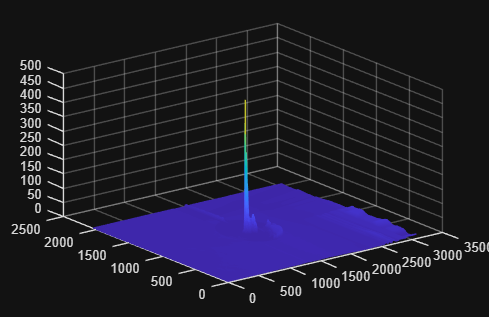

mesh(scaledLuminanceMap)

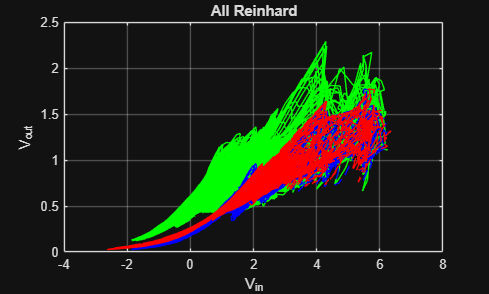



figure;
plot(log(Vin3(:,:,1)), Vout3(:,:,1), 'g-');
hold on
plot(log(Vin(:,:,1)), Vout(:,:,1), 'b--');
plot(log(Vin2(:,:,1)), Vout2(:,:,1), 'r--');

title('All Reinhard');
xlabel('V_{in}');
ylabel('V_{out}');
grid on;
hold off

% ACES with camera response curve


aces_input_converter = [
    0.59719, 0.35458, 0.04823;
    0.07600, 0.90834, 0.01566;
    0.02840, 0.13383, 0.83777];

aces_output_converter = [ 
    1.60475, -0.53108, -0.07367;
    -0.10208,  1.10813, -0.00605;
    -0.00327, -0.07276,  1.07602];
ACES = zeros(size(Vin3, 1), size(Vin3, 2), 3);
Vin = HDR_cam
% Loop through each pixel and compute the dot product
for i = 1:size(Vin, 1)
    for j = 1:size(Vin, 2)
        %size(HDR(i, j, :))
        %size(reshape(HDR(i, j, :),1,[]))
        ACES(i, j, :) = aces_input_converter * reshape(Vin(i, j, :),1,[])';
    end
end
%v = aces_input_converter * HDR;
a = ACES .* (ACES + 0.0245786) - 0.000090537;
b = ACES .* (0.983729 * ACES + 0.4329510) + 0.238081;
newColour = a ./ b;
%outputColour = aces_output_converter .* newColour;
% Loop through each pixel and compute the dot product
for i = 1:size(newColour, 1)
    for j = 1:size(newColour, 2)
        ACES(i, j, :) = aces_output_converter * reshape(newColour(i, j, :),1,[])';
    end
end

plot(log(Vin(:,:,1)), ACES(:,:,1), 'b--', 'LineWidth', 2);

ACES_cliped = clip(ACES, 0, 1)
imshow(ACES_cliped)
imshow(Vout2);

max_white = max(max(ACES))
numerator = ACES .* (1.0 + (ACES ./ (max_white .* max_white)));
ACES_with_Reinhard = numerator ./ (1.0 + ACES);
imshow(ACES_with_Reinhard)


% Local Gausian Reinhard 
Vin = HDR;
% Create luminance map from HDR image using the relative luminance
% https://en.wikipedia.org/wiki/Relative_luminance
luminanceMap = 0.2126 * Vin(:,:,1) + 0.7152 * Vin(:,:,2) + 0.0722 * Vin(:,:,3);
figure;
imshow(luminanceMap, []);
title('Luminance Map from HDR Image');

normalKey = 0.05;%0.18; % UNDER EQ 2

alpha = 0.3; % 0.3 for EQ 5
phi = 8;%8; % for EQ 7, gör inget?
epsilon = 0.05; % for EQ 8, typ sm områden storlek



% Reinhards paper - Photographic Tone Reproduction for Digital Images
% https://www-old.cs.utah.edu/docs/techreports/2002/pdf/UUCS-02-001.pdf

sizeX = size(luminanceMap,1);
sizeY = size(luminanceMap,2);
zones = 10;

Vi = zeros(sizeX, sizeY, zones);
V = zeros(sizeX, sizeY, zones);
sm(1:sizeX, 1:sizeY) = zones;

% create and filter the luminanceMap with different levels EQ 5 & 6
for scale=1:(zones+1)
    s = 1.6 ^ (scale-1);
    sigma = alpha * s;
    % kernelRad = ceil(2*sigma);
    %kernelSize = 2*kernelRad+1;      
    
    Vi(:,:,scale) = imgaussfilt(luminanceMap, sigma);

    %gaussKerHori = fspecial('gaussian', [kernelSize 1], sigma);
    %v1(:,:,scale) = conv2(lumMap, gaussKerHori, 'same');
    %gaussKerVer = fspecial('gaussian', [1 kernelSize], sigma);
    %v1(:,:,scale) = conv2(v1(:,:,scale), gaussKerVer, 'same');
end

% equation 7 
for i = 1:zones    
    V(:,:,i) = (Vi(:,:,i)) - Vi(:,:,i+1) ./ (normalKey*(2^phi) / (s^2) + Vi(:,:,i));    
end  


% equation 8
for x=1:sizeX
    for y=1:sizeY
        %bestValue = inf;
        for scale=1:zones
            % the largest area around a given pixel where no large contrast changes occur
            if abs(V(x,y,scale)) > epsilon                    
               if (scale == 1) 
                    sm(x,y) = 1;
                end
                % maybe rewrite
                if (scale > 1)
                    sm(x,y) = scale;
                end                   
                break;
            end
            
            %if abs(V(x,y,scale)) < bestValue
            %    bestValue = abs(V(x,y,scale));
            %    sm(x,y) = scale;
            %end

        end
    end
end

% if we have not given a value, set highest
%index = find(sm == 0);
%sm(index) = zones;    
ViFinal = zeros(sizeX, sizeY);

% we seek the first scale sm where: EQ 8 is true
% for each pixel, select the correct one
for x=1:sizeX
    for y=1:sizeY
        ViFinal(x,y) = Vi(x,y,sm(x,y));
    end
end

% scake luminance map EQ 1 & 2
delta = 0.001; 

numPixels = sizeX * sizeY
sumLog = 0;
for x=1:sizeX
    for y=1:sizeY
        sumLog = sumLog + log(delta + luminanceMap(x,y));
    end
end

logAverageSmallLuminance = exp((1/numPixels) * sumLog)

a = 2.42; % key value

scaledLuminanceMap = a * luminanceMap/ logAverageSmallLuminance;

% EQ 9 local dodging-and-burning operator
newLuminanceMap = scaledLuminanceMap ./ (1 + ViFinal);
mesh(newLuminanceMap)

% need to convert new luminance to an image with colour
% Gradient Domain High Dynamic Range Compression
% https://www.cs.huji.ac.il/~danix/hdr/hdrc.pdf
newImage = zeros(size(Vin));

saturation = 0.4;
Cout = (Vin./luminanceMap).^saturation .* newLuminanceMap;
imshow(Cout) 



smImage = zeros(size(Vin));
scale = floor(255/zones)
imshow(sm.*scale, [0,255])


max(max(sm))
for x=1:sizeX
    for y=1:sizeY
        if sm(x,y) == 1
            smImage(x,y,:) = [0,0,0];
        elseif sm(x,y) == 2
            smImage(x,y,:) = [1,0,0];
        elseif sm(x,y) == 3
            smImage(x,y,:) = [0,1,0];
        elseif sm(x,y) == 4
            smImage(x,y,:) = [0,0,1];
        elseif sm(x,y) == 5
            smImage(x,y,:) = [1,1,0];
        elseif sm(x,y) == 6
            smImage(x,y,:) = [1,0,1];
        elseif sm(x,y) == 7
            smImage(x,y,:) = [0,1,1];
        else 
            smImage(x,y,:) = [1,1,1];
        end
    end
end

imshow(smImage)

% Durand's Local Tone Mapping
Vin = HDR;
% Create luminance map from HDR image using the relative luminance
% https://en.wikipedia.org/wiki/Relative_luminance
luminanceMap = 0.2126 * Vin(:,:,1) + 0.7152 * Vin(:,:,2) + 0.0722 * Vin(:,:,3);
figure;
imshow(luminanceMap, []);
title('Luminance Map from HDR Image');

% Chrominance channels
Rc = Vin(:,:,1) ./ luminanceMap(:,:);
Gc = Vin(:,:,2) ./ luminanceMap(:,:);
Bc = Vin(:,:,3) ./ luminanceMap(:,:);

% Log luminance map
logH = log(luminanceMap);

% https://se.mathworks.com/help/images/ref/imbilatfilt.html
DoS = 50;
B = imbilatfilt(logH,DoS);
imshow(B)
title(['Degree of Smoothing: ',num2str(DoS)])

D = logH - B;

% Compress the base
contrast = 2.0;
gamma = contrast / (max(max(B)) - min(min(B)));
Bprim = gamma .* B;

% Compute the result
%newLuminanceMapDurand = exp(Bprim + D);
newLuminanceMapDurand = 10.^(Bprim + D);
imshow(newLuminanceMapDurand)

saturation = 0.05;
Cout = (Vin./luminanceMap).^saturation .* newLuminanceMapDurand;
imshow(Cout)

Rprim = Rc .* newLuminanceMapDurand;
Gprim = Gc .* newLuminanceMapDurand;
Bprim = Bc .* newLuminanceMapDurand;

newHDR(:,:,1) = Rprim;
newHDR(:,:,2) = Gprim;
newHDR(:,:,3) = Bprim;

% source? 
tonemappedHDR = newHDR/(10.^(gamma*(max(max(B)) ) )).^0.4;
newLDR = clip(tonemappedHDR, 0, 1);
imshow(newLDR)

Vin = HDR;
% Create luminance map from HDR image using the relative luminance
% https://en.wikipedia.org/wiki/Relative_luminance
luminanceMap = 0.2126 * Vin(:,:,1) + 0.7152 * Vin(:,:,2) + 0.0722 * Vin(:,:,3);
mesh(luminanceMap)
colorbar
mesh(0.2126 * newLDR(:,:,1) + 0.7152 * newLDR(:,:,2) + 0.0722 * newLDR(:,:,3))



% This section is from the paper 
% HDR-Debevec-97.pdf


% gsolve.m − Solve for imaging system response function
%
% Given a set of pixel values observed for several pixels in several
% images with different exposure times, this function returns the
% imaging system's response function g as well as the log film irradiance
% values for the observed pixels.
%
% Assumes:
%
% Zmin = 0
% Zmax = 255
%
% Arguments:
%
% Z(i,j) is the pixel values of pixel location number i in image j
% B(j) is the log delta t, or log shutter speed, for image j
% l is lamdba, the constant that determines the amount of smoothness
% w(z) is the weighting function value for pixel value z
% 
% Returns:
%
% g(z) is the log exposure corresponding to pixel value z
% lE(i) is the log film irradiance at pixel location i
%

function [g,lE]=gsolve(Z,B,l,w)
    n = 256;
    A = zeros(size(Z,1)*size(Z,2)+n+1,n+size(Z,1));
    b = zeros(size(A,1),1);
    %% Include the data−fitting equations
    k = 1;
    for i=1:size(Z,1)
        for j=1:size(Z,2)
            wij = w(Z(i,j)+1);
            A(k,Z(i,j)+1) = wij; 
            A(k,n+i) = -wij; 
            b(k,1) = wij * B(j);
            k=k+1;
        end
    end
    %% Fix the curve by setting its middle value to 0
    A(k,129) = 1;
    k=k+1;
    %% Include the smoothness equations
    for i=1:n-2
     A(k,i)=l*w(i+1); A(k,i+1)=-2*l*w(i+1); A(k,i+2)=l*w(i+1);
     k=k+1;
    end
    %% Solve the system using SVD
    x = A\b;
    g = x(1:n);
    lE = x(n+1:size(x,1));
end

